# Walk step counter


%% Walk Step Counter Using MATLAB Mobile Sensor Data
clc; clear; close all;

## Step-1 Load the Sensor Data

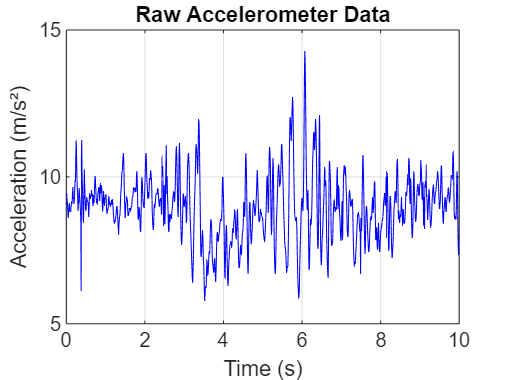


load('sensorlog_20250405_131808.mat');

%% Identify Time & Acceleration Variables Dynamically
vars = whos;
timeVar = ''; 
accelVar = '';

for i = 1:length(vars)
    if contains(vars(i).name, 'time', 'IgnoreCase', true)
        timeVar = vars(i).name;
    elseif contains(vars(i).name, 'acc', 'IgnoreCase', true) || ...
           contains(vars(i).name, 'acceler', 'IgnoreCase', true)
        accelVar = vars(i).name;
    end
end

%% Ensure Time & Acceleration Variables Exist Before Proceeding
if ~isempty(timeVar)
    time = evalin('base', timeVar);
    if istimetable(time), time = time.Variables; end
    if istable(time), time = table2array(time); end
else
    time = linspace(0, 10, size(evalin('base', accelVar), 1)); % Create synthetic time
end

if ~isempty(accelVar)
    AccData = evalin('base', accelVar);
    if istimetable(AccData), AccData = AccData.Variables; end
    if istable(AccData), AccData = table2array(AccData); end
else
    AccData = zeros(length(time), 3); % Default to zero if missing
end

%% Extract Z-Axis Acceleration
AccZ = AccData(:, 3);

%% Plot Raw Acceleration Data
figure;
plot(time, AccZ, 'b'); grid on;
xlabel('Time (s)'); ylabel('Acceleration (m/s²)');
title('Raw Accelerometer Data');

## Step-2: Remove Trend

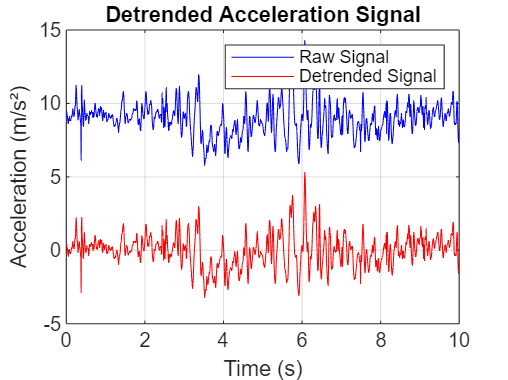

Detrended_signal = detrend(AccZ);

%% Plot Detrended Signal
figure;
plot(time, AccZ, 'b'); hold on;
plot(time, Detrended_signal, 'r'); grid on;
legend('Raw Signal', 'Detrended Signal');
xlabel('Time (s)'); ylabel('Acceleration (m/s²)');
title('Detrended Acceleration Signal');

## Step 3: Convert to Frequency Domain

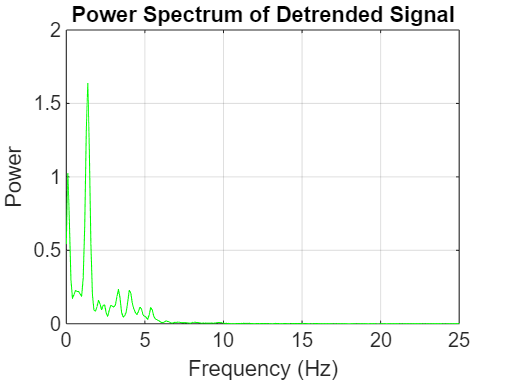

fs = 50;  
[pxx, fxx] = pwelch(Detrended_signal, [], [], [], fs);

%% Plot Frequency Spectrum
figure;
plot(fxx, pxx, 'g'); grid on;
xlabel('Frequency (Hz)'); ylabel('Power');
title('Power Spectrum of Detrended Signal');

## Step 4: Design & Apply Low-Pass Filter

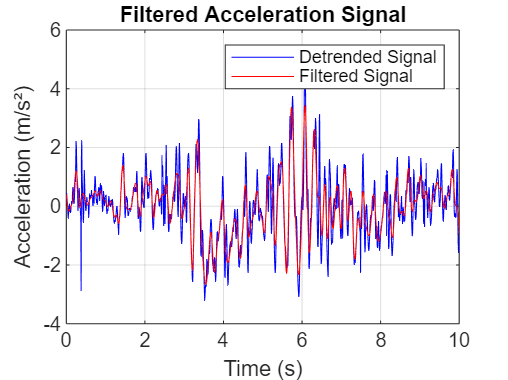

N  = 5;  
Fc = 3;  
h  = fdesign.lowpass('N,F3dB', N, Fc, fs);
Hd = design(h, 'butter');
Filtered_signal = filtfilt(Hd.sosMatrix, Hd.ScaleValues, Detrended_signal);

%% Plot Filtered Signal
figure;
plot(time, Detrended_signal, 'b'); hold on;
plot(time, Filtered_signal, 'r'); grid on;
legend('Detrended Signal', 'Filtered Signal');
xlabel('Time (s)'); ylabel('Acceleration (m/s²)');
title('Filtered Acceleration Signal');

## Step 5: Perform Filter Delay Compensation

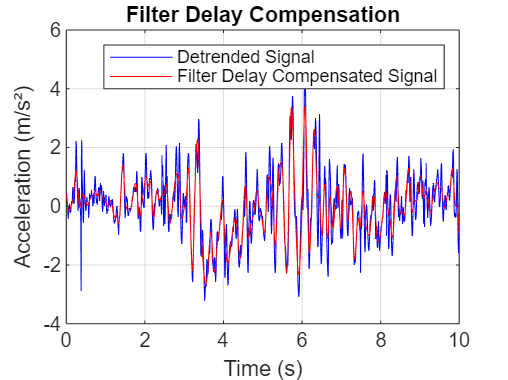

filter_output_nodelay = filtfilt(Hd.sosMatrix, Hd.ScaleValues, Detrended_signal);

%% Plot Delay Compensated Signal
figure;
plot(time, Detrended_signal, 'b'); hold on;
plot(time, filter_output_nodelay, 'r'); grid on;
legend('Detrended Signal', 'Filter Delay Compensated Signal');
xlabel('Time (s)'); ylabel('Acceleration (m/s²)');
title('Filter Delay Compensation');

## Step 6: Step Detection

[peaks, locs] = findpeaks(filter_output_nodelay, 'MinPeakHeight', 0.3, 'MinPeakDistance', 15);
StepCount = length(locs);

%% Display Step Count
disp(['Total Steps Detected: ', num2str(StepCount)]);

Total Steps Detected: 33


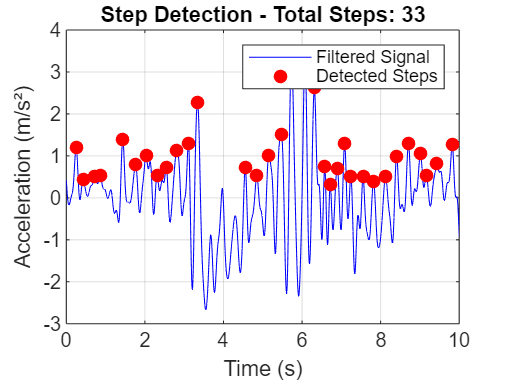


%% Visualize Step Detection
figure;
plot(time, filter_output_nodelay, 'b'); hold on;
plot(time(locs), peaks, 'ro', 'MarkerFaceColor', 'r'); grid on;
legend('Filtered Signal', 'Detected Steps');
xlabel('Time (s)'); ylabel('Acceleration (m/s²)');
title(['Step Detection - Total Steps: ', num2str(StepCount)]);